addpath('functions/');

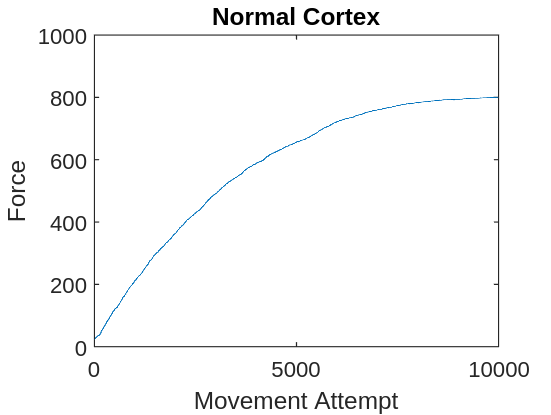

% Creating n Corticalspinal cells
n = 1000; 

% Initalize the base CS cells
x_0 = -1 + (1+1)*rand(1, n);
% 80% of the n Cortical cells are M1
agonist_count = n * 0.99;
agonist = randperm(agonist_count);
m1_count = agonist_count * 0.8;

% Parameters for zero-mean normal distribution
std_dev = 0.02;
mean = 0;

% CS extensor and flexor connection weights
c_fi = ones(1, n);
for i = 1:length(c_fi)    
    if i > m1_count
        % SMA
        c_fi(i) = 0.1*c_fi(i);
    end
end

% Translating MN pool to force
delta = 1;

sma = [];
m1 = [];
final_forces = [];
trials = [];
f_final_net = 0;
max_trials = 10000;
for trial = 1:max_trials
    v_i = std_dev.*randn(1, n) + mean;
    x_i = x_0 + v_i;
    
    % Activations
    m1_activation = 0;
    for i = 1:800
        m1_activation = m1_activation + x_0(i);
    end
    sma_activation = 0;
    for i = 801:1000
        sma_activation = sma_activation + x_0(i);
    end
    
    s_fi = 0;
    % Flexor MN Pools translated to force
    for i = 1:length(agonist)
        ind = agonist(i);
        
        if i > m1_count
            % SMA
            temp = g_fi(x_i(ind), c_fi(ind));
            s_fi = s_fi + temp;
        else
            % M1
            temp = g_fi(x_i(ind), c_fi(ind));
            s_fi = s_fi + temp;
        end
    end
    f_f = delta * s_fi;

    % Net force
    f_net = f_f;

    if f_net > f_final_net
        f_final_net = f_net;
        x_0 = x_i;
    end
    
    sma = [sma, sma_activation];
    m1 = [m1, m1_activation];
    final_forces = [final_forces, f_final_net];
end

plot(final_forces)
title("Normal Cortex")
ylim([0, n])
ylabel('Force')
xlabel('Movement Attempt')

saveas(gcf,'images/NormalCortex.png')

Final Activations

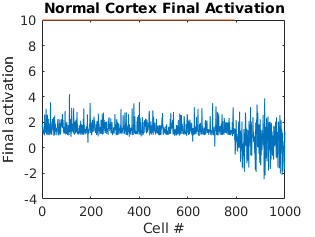

plot(x_0)
hold on
plot(10 * ones(1, m1_count))
hold off
title("Normal Cortex Final Activation")
ylabel("Final activation")
xlabel("Cell #")

saveas(gcf, 'images/NormalCortexActivations.png')

Net Activations compared to Forces

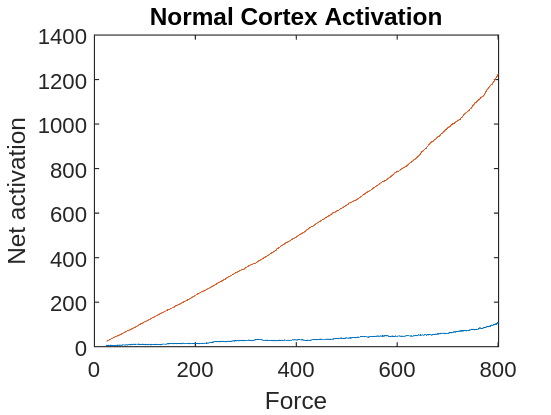

plot(final_forces, sma)
hold on
plot(final_forces, m1)
hold off

title("Normal Cortex Activation")
ylabel("Net activation")
xlabel("Force")

saveas(gcf, 'images/NormalCortexNetActivations.png')